# Cargar los datos

Funciones útiles

plot_MRI(V), hace lo del reshape y montage solo

kmeans_p, te devuelve el resultado altiro sin utilizar lo de reshape al vector que te devuelve kmeans. (Ve las funciones que tienen instrucciones)

Data.mat, tiene todos los cortes.

N, es para seleccionar el corte, N = [1,7]. Estabamos viendo el 4 y y el 3 parece

4, es corte sagital

clear all
load('Data.mat')
rng(1);
N = 4;
Indice = [foto.class] == N;
Fotos = foto(Indice);
V = zeros([size(Fotos(1).data) numel(Fotos)]);
se = strel('disk',5);

for k=1:numel(Fotos)
    Im = imadjust(imgaussfilt(im2single(Fotos(k).data),0.5)); 
    Im = adapthisteq(Im + imtophat(Im,se) - imbothat(Im,se));
    V(:,:,k) = Im;
end

figure;
plot_MRI(V)



# Pruebas de Segmentación con Kmeans

Kmeans, lo que hace basicamente, es encontrar clusters (Grupos), en un espacio de características. Pero no es supervisado, es decir, no sabe que es cada grupo, solamente encuentro relaciones entre puntos.

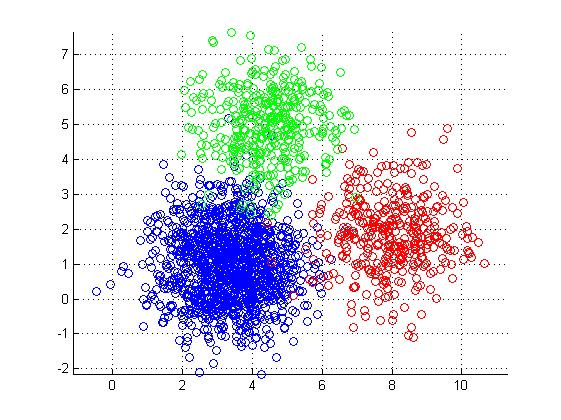

Prueba 1:

Haremos K-means, con 3 clusters solo pasando como características las Intensidades del Volumen V, de la forma V(:), y luego intentaremos, seleccionando el cluster más adecuado, encontrar una máscara para aplicar el filtro_gabriel, que incrementará las zonas de interes de la Máscara,

 Lo que hace el filtro:

    Zonas de la región, o sea Mask(x,y) =1:


$$I\left(x,y\right)=I\left(x,y\right)+{I\left(x,y\right)}^{\alpha }$$
 

    Zonas Mask(x,y) = 0;

    
$$\mathrm{I(x , y) = }\left(\frac{I\left(x,y\right)}{\beta }\right)$$


Se usan alpha y beta como 1.6 y 1.3 respectivamente, se pueden modificar, pero son los que usaron gabriel

I) Hacemos K-means y escojemos un Cluster para utilizar


V_kmeans1 = kmeans_p(V(:),3,size(V));
Mask1 = logical(V_kmeans1==1);
figure;
plot_MRI(Mask1)

II) Arreglamos un poco la máscara con operaciones morfológicas

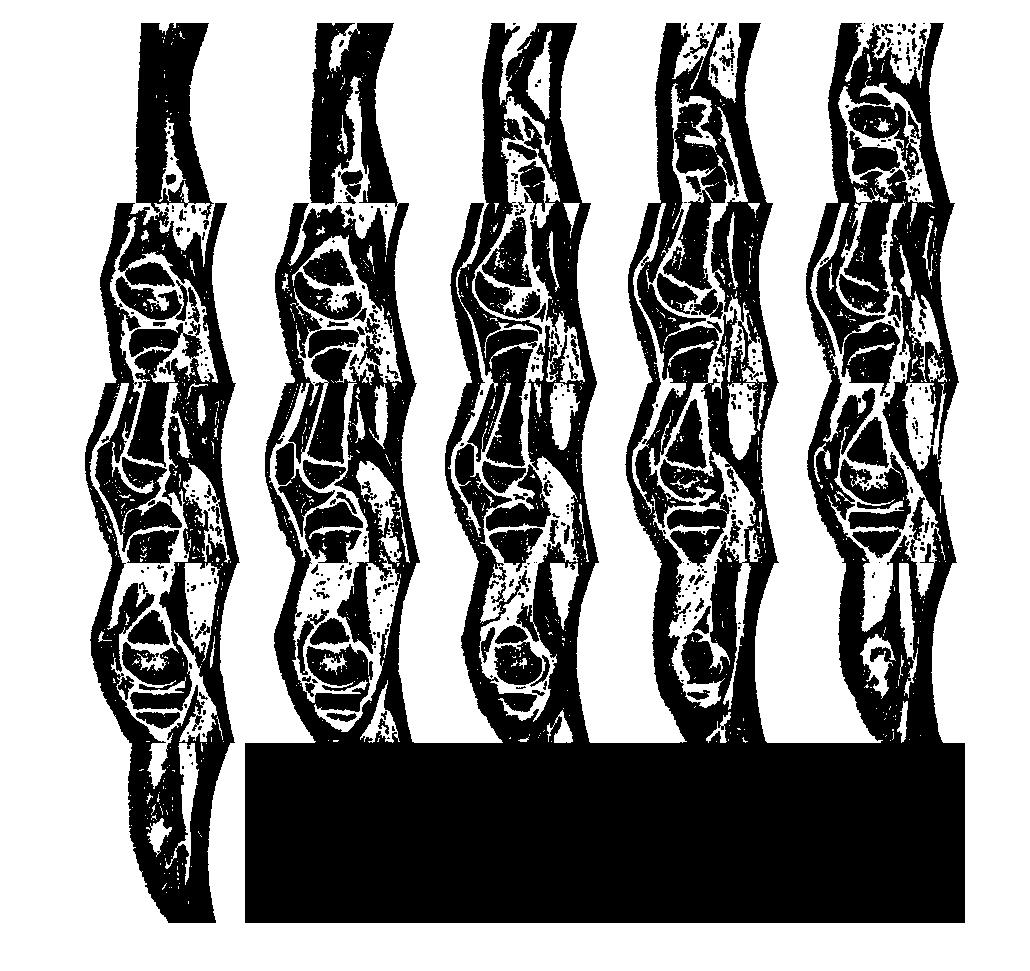


Mask1 = logical(V_kmeans1==1);
Se1 = strel('disk',5);
Se2 = strel('disk',2);
Mask1 = imclose(Mask1,Se1);
%Mask1 = im(Mask1,Se2);

plot_MRI(Mask1)